# **Ejercicio 3**

## T2.3 Método de Muller

#### Grupo 8: Ana Robledano Abasolo, Alfredo Robledano Abasolo, 

####                 Melani Tatayo Culchas, Rubén Sierra Serrano.

a) Escribe una función de Matlab que calcule las raíces de un polinomio mediante 

el método de Müller. Nombra a la función: 

`r = ``M``uller(fun,``a``,``b, ``ermax)` 

donde: 

`fun` = función dada en forma anónima f=@(x) 

`(a, b) `= intervalo donde se encuentra la raíz 

`ermax` = error máximo 

La función debe comenzar calculando los valores de `fun` en `a, b` y el punto 

medio del intervalo `(a, b``)` que tomará como $x_0 {,\;x}_1$ y ${\;x}_2$ respectivamente. 

b) Resuelve mediante la función anterior el siguiente problema: 

Al tratar de encontrar la acidez de una solución de hidróxido de magnesio en 

ácido clorhídrico, se obtiene la ecuación siguiente: 


$$A\left(x\right)=x^3 -3\ldotp 5x^2 -40$$
 

donde x es la concentración del ion hidronio. Calcule la concentración del ion 

hidronio para una solución saturada (cuando la acidez es igual a cero). Dibuja 

previamente la función para aproximar el intervalo donde se encuentra la raíz. 

Da la respuesta con un error menor que ${10}^{-6}$. Comprueba el resultado con el 

comando `roots` de Matlab y verifica si el error es el esperado. 

Preparamos el entorno de trabajo

clc;
clear;
close all;

Zona de declaración, declaramos la función, el intervalo y un vector con los coeficientes de la función

f = @(x) x.^3 - 3.5.*x.^2 - 40;
x = linspace(-10,10);
p = [1 -3.5 0 -40];

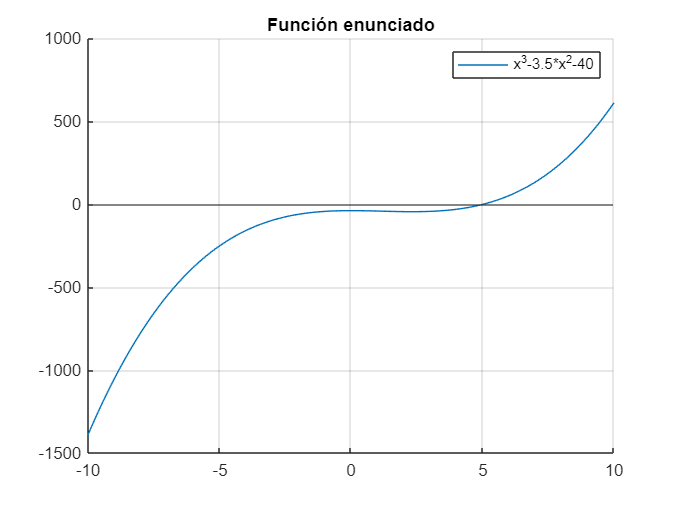

hold on
grid on
plot(x, f(x))
yline(0)
legend('x^{3}-3.5*x^{2}-40')
title("Función enunciado")
hold off

Calculamos las raíces con el método de Muller y las  mostramos

sol_muller = Muller(f,0,7,1e-6);
% Se convierte en tabla los datos obtenidos
tabla_sol_muller = array2table(sol_muller, 'VariableNames', "Soluciones Muller");
disp("Las soluciones con Muller son:")

Las soluciones con Muller son:


disp(tabla_sol_muller)

    Soluciones Muller
    _________________

         5.0614      



Calculamos las raíces con la función roots()

sol_roots = roots(p);
sol_roots = sol_roots(imag(sol_roots)==0); % nos quedamos solo con la real
tabla_sol_roots = array2table(sol_muller, 'VariableNames', "Soluciones roots()");
disp("Las soluciones con roots() son:")

Las soluciones con roots() son:


disp(tabla_sol_roots)

    Soluciones roots()
    __________________

          5.0614      

